## Microsaccade analysis example live script

This shows all the steps for one person with comments, needs to be a mde a function with filemt input

First clear workspace and load an example person

clear
cd /Users/andreaskeil/As_Exps/condispas/Condispas_EyeTracking/density_analysis
load('spa308.asc.eyeout.mat')

The resulting eyelinkout object already has the artifact corrected (interpolated) data in 3-D: 

mat3d = eyelinkout.matcorr;
size(mat3d)

ans =            3        2001         350


Here, the first two rows are hori and verti gaze, the third is pupil, which we do not need for this analysis. We do need a time axis for the plots and fior finding time segments of interest though. 

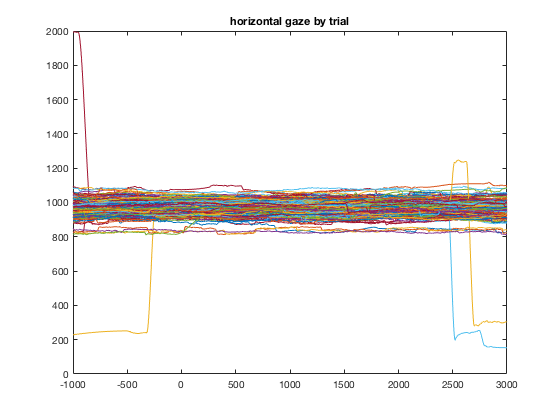

gazemat =  mat3d(1:2,:,:); 
taxis = -1000:2:3000;
figure(1), plot(taxis, squeeze(gazemat(1,:,:))), title('horizontal gaze by trial')

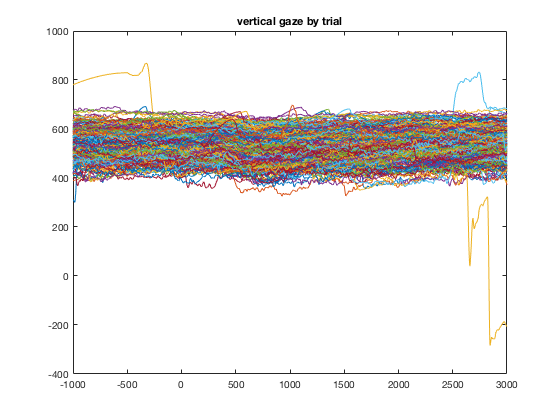

figure(2), plot(taxis, squeeze(gazemat(2,:,:))), title('vertical gaze by trial')


% matt/Roxy, here we need to throw out saccades > 1 degrees. most people
% did that by discarding the entire trial

% to do this, we should convert into degrees of visual angle - Q should we
% do this in 2D or separately for hor and verti

Ok, now we can calculate velocities, by just taking the first derivative, still leaving hori and verti separate, then smooth each

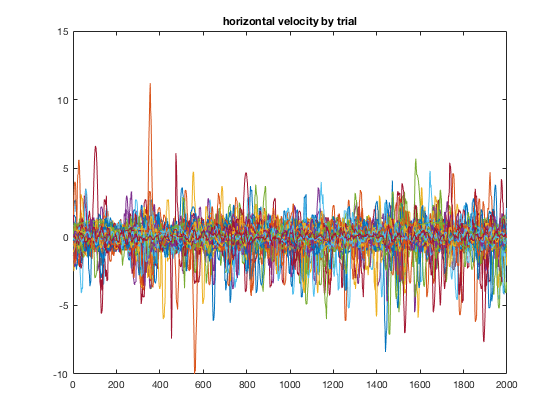

gazemat =  mat3d(1:2,501:1500,:); 
velocitymat = diff(gazemat, 1, 2);
taxis = taxis(502:1500); 
figure(3), plot(taxis, squeeze(velocitymat(1,:,:))), title('horizontal velocity by trial')

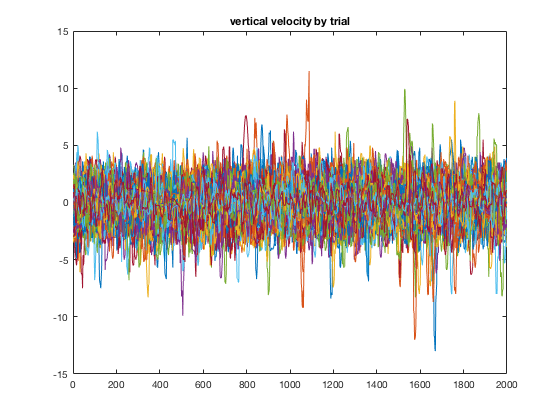

figure(4), plot(taxis, squeeze(velocitymat(2,:,:))), title('vertical velocity by trial')

Now smooth them

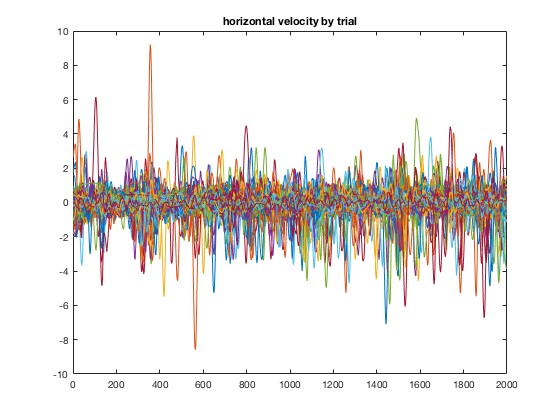

smoothgazemat = movmean(velocitymat, 6, 2); 
figure(5), plot(taxis, squeeze(smoothgazemat(1,:,:))), title('horizontal velocity by trial')

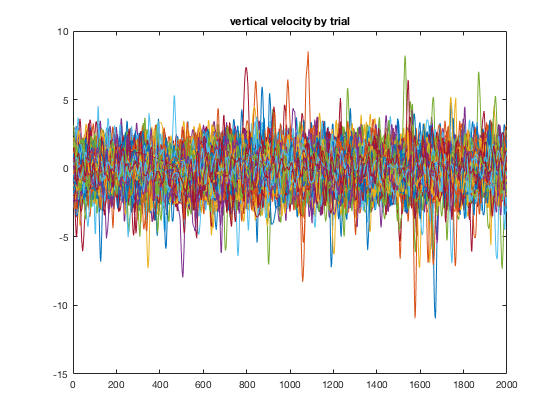

figure(6), plot(taxis, squeeze(smoothgazemat(2,:,:))), title('vertical velocity by trial')

Now plot as 2-D

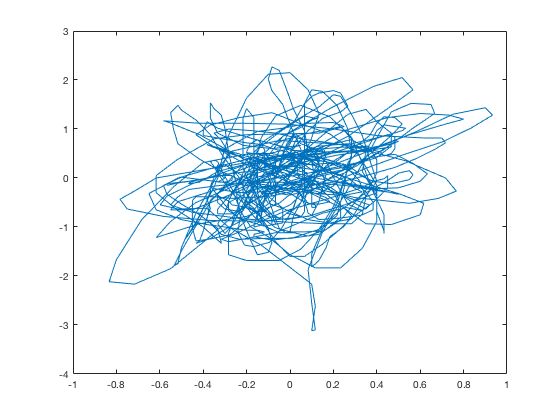

figure(6), 
trial = 14; 
plot(squeeze(smoothgazemat(1,:,trial)), squeeze(smoothgazemat(2,:,trial)))